%Created by Diego Tristán-Rodríguez

%This is the main code, it is partitioned into 4 segments, the first
%segment is asigned to run the PSO algorithm, the second one is to obtain
%all the statistic results, the tird is to simulate the system response
%with the best result obtained from the PSO algorithm, finally the fourth
%part is to visualize the evolution of the fitness function and the
%particles in each dimension.

clear all
clc 
numProves = 30; %Number of runs.
tic
parfor i = 1:numProves 
    tic
        PSOND(i); %Call to the PSOT algorithm function.
        RPSOND(i); %Call to the RPSOT algorithm funcition.
    tf = toc;
    %Visualize the time consumption for each run.
    disp("Proceso " + num2str(i) + " se tardó: " + num2str(tf))
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
Proceso 5 se tardó: 2186.7537
Proceso 6 se tardó: 2227.4498
Proceso 1 se tardó: 2357.4221
Proceso 4 se tardó: 2387.9283
Proceso 2 se tardó: 2847.0537
Proceso 3 se tardó: 2883.926
Proceso 14 se tardó: 2321.9581
Proceso 8 se tardó: 2208.7505
Proceso 13 se tardó: 2329.1977
Proceso 16 se tardó: 2293.5898
Proceso 7 se tardó: 2642.3062
Proceso 15 se tardó: 2740.084
Proceso 18 se tardó: 2480.1628
Proceso 17 se tardó: 2637.6816
Proceso 10 se tardó: 2324.6532
Proceso 12 se tardó: 2580.382
Proceso 9 se tardó: 2263.2382
Proceso 11 se tardó: 2311.8712
Proceso 22 se tardó: 2483.993
Proceso 19 se tardó: 2386.559
Proceso 21 se tardó: 2562.58
Proceso 20 se tardó: 2518.1992
Proceso 23 se tardó: 2438.9559
Proceso 24 se tardó: 2538.9331
Proceso 27 se tardó: 2267.5622
Proceso 25 se tardó: 2582.3116
Proceso 26 se tardó: 2493.5361
Proceso 29 se tardó: 2446.5486
Proceso 28 se tardó: 2457.6895
Proceso

tfProc = toc

tfProc = 1.2661e+04

%File to save the time taken.
if exist("time.mat", 'file') ~= 2
    save("time.mat")
end

%This code obtains the statistic results.
if exist("time.mat", 'file') == 2
    load("time.mat")
end
p = load("proceso_" + num2str(1) + ".mat");

for i = 1:30
    p(i) = load("proceso_" + num2str(i) + ".mat");
end
p(:).JgBest

ans = 16.7449

ans = 16.2729

ans = 16.0805

ans = 15.7042

ans = 15.9113

ans = 17.1020

ans = 15.8475

ans = 17.2318

ans = 15.9542

ans = 15.7488

ans = 15.4762

ans = 16.8673

ans = 17.2521

ans = 15.7924

ans = 16.3279

ans = 15.9551

ans = 17.1975

ans = 16.3170

ans = 18.3811

ans = 15.9659

ans = 15.9050

ans = 15.7640

ans = 17.6250

ans = 16.7498

ans = 15.6994

ans = 15.6938

ans = 15.9314

ans = 15.5961

ans = 16.6437

ans = 16.6820

[minJ, idMinJ] = min([p(:).JgBest])

minJ = 15.4762

idMinJ = 11


%Set of best parameters.
resG = p(idMinJ).gBest

resG = 1.0e+04 *

    0.0032    0.0262    0.0252    2.2789    0.0032


%Mean of the fitness function evaluations.
meann = mean([p(:).JgBest])

meann = 16.3474

%Median of the fitness function evaluations.
mediann = median([p(:).JgBest])

mediann = 16.0232

%Standard deviation of the fitness function evaluations.
dvstd = std([p(:).JgBest])

dvstd = 0.7042

%Eigenvalues related to the controller polinomial.
eigsC = getEigenvalues(resG(1), resG(2))

eigsC =  -16.1379 - 1.1550i -16.1379 + 1.1550i


%Eigenvalues related to the extended observer polinomial.
eigsO = getEigenvalues3(resG(3), resG(4), resG(5))

eigsO =  -90.4524 + 0.0000i
 -80.9035 +40.0927i
 -80.9035 -40.0927i


%Damping ratio asociated to the controller polinomial.
xic =  resG(1)/(2*sqrt(resG(2)))

xic = 0.9974

%Save the statistic results.
save("test1");
%Load the best run.
load("proceso_" + int2str(idMinJ));

%This code generates the curves that shows the system response in
%closed-loop with the gains obtained by means of the PSO algorithm

close all
tic
[J, y, x1q, rv, uVal, duVal, t] = simDyn(resG);
toc

Elapsed time is 1.931828 seconds.


J

J = 15.9495

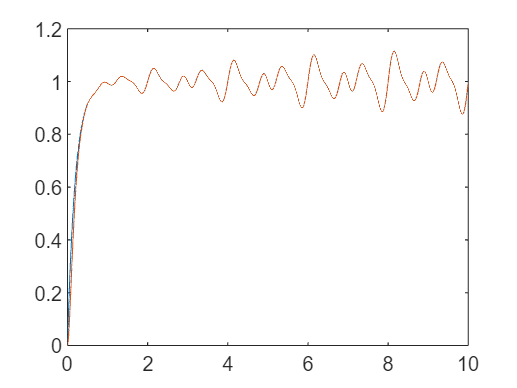

figure
plot(t, rv);
hold on
plot(t, x1q);

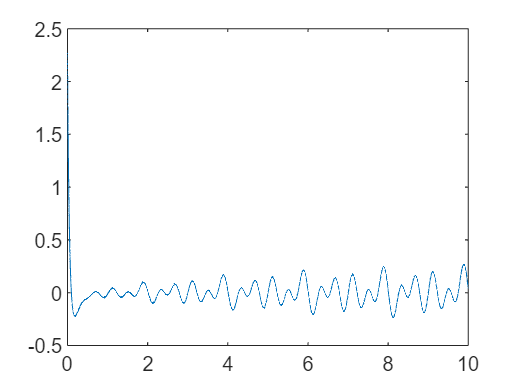

xlabel("time [sec]");
ylabel("System response");
legend("Reference", "Response");

figure
plot(t, uVal);

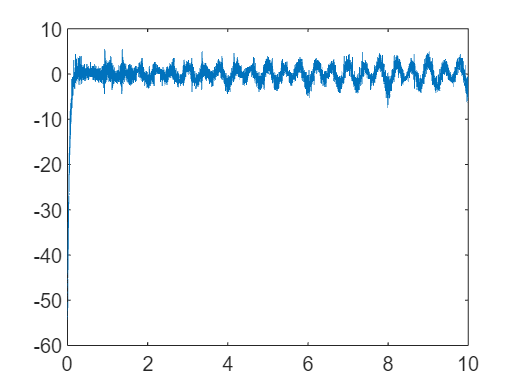

xlabel("time [sec]");
ylabel("Control signal");


figure
plot(t(1:end-1), duVal);

xlabel("time [sec]");
ylabel("Control signal variation");

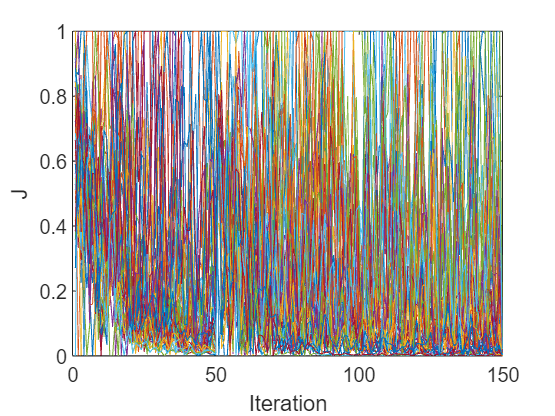

%This code plot the evolution of the fitness function and the particles in
%each dimention.
clf
plot(disHist(:, :)')
xlabel("Iteration");
ylabel("J");

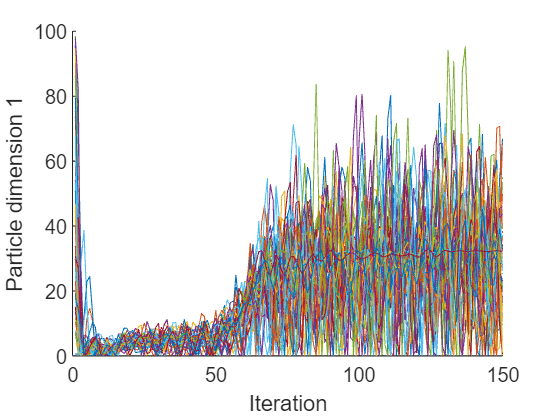

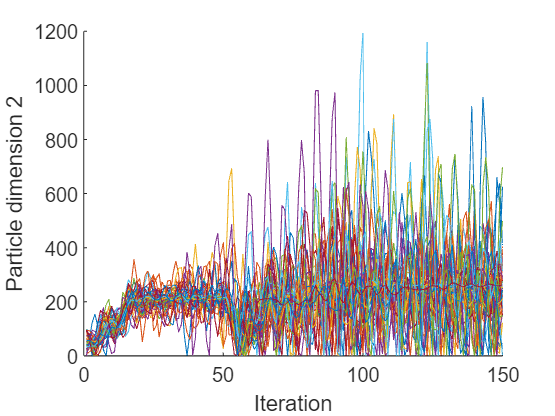

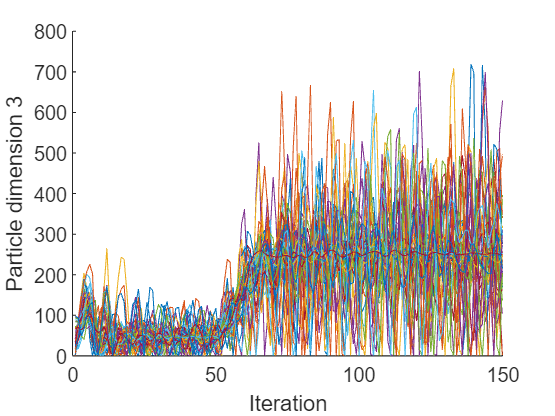

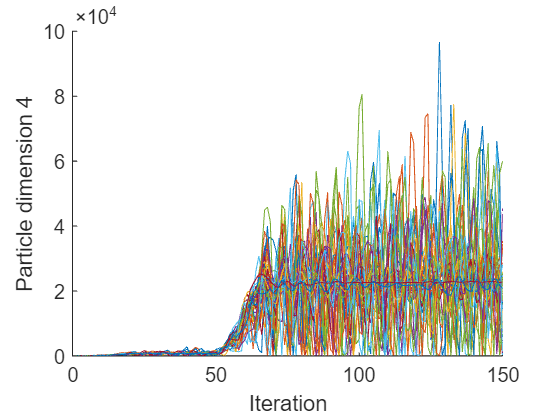

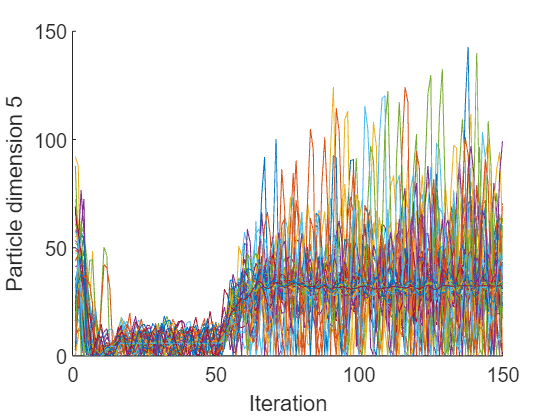

for j = 1:nVar
    figure;
    hold on
    for i = 1:nP
        plot(reshape(zHist(i, j, :), 1, nIt))
        % legend
    end
    xlabel("Iteration");
    ylabel("Particle dimension " + int2str(j));
end

function y = getEigenvalues(d1, d2)
    eig1 =  - d1/2 - sqrt(d1^2 - 4*d2)/2;
    eig2 = sqrt(d1^2 - 4*d2)/2 - d1/2;
    y = [eig1, eig2];
end
function y = getEigenvalues3(d1, d2, d3)
    y = roots([1, d1, d2, d2*d3]);
end